## Modell

clear all
clf
A = kron(eye(2),[0 1; 0 0]);
const = -5/7*9.81*0.3/2;
B = kron(eye(2),[0;1])*const;
C = kron(eye(2),[1 0]);
sys = ss(A,B,C,0,0,  'Name'      ,'Ball on Plate - Linear' ,...
                     'StateName' ,["xPos" "xGeschw." "yPos" "yGeschw."],...
                     'OutputName',["X Position","Y Position" ]         ,...
                     'OutputUnit',[     "m"    ,   "m"       ]         ,...
                     'InputName' ,[ "Motor A" "Motor B"      ] ,...
                     'InputUnit' ,[    "rad"    "rad"        ] ,...
                     'TimeUnit'  , 's');
dsys = c2d(sys,1/30);
clearvars -except dsys

## Labyrinth Pfad

load("labyrinthPfad.mat")
ptx = pt(1:end-4,1)*0.188/240;
pty = pt(1:end-4,2)*0.233/300;

w = [ptx pty];

open("Modell_PID.slx")
clearvars -except dsys w

y = out.ymodel.OutputData;
w = out.w_vs_model.OutputData;
t = 0:1/30:(size(y,1)-1)/30;

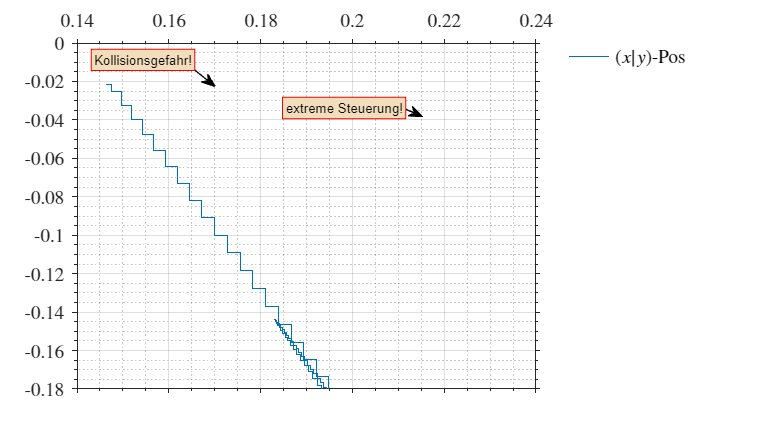

clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);

% Create axes
axes1 = axes('Parent',figure1,'Position',[0.1 0.1 .8 .8],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
hold(axes1,'on');

% Create stairs
stairs(y(:,1),-y(:,2),DisplayName='$(x|y)$-Pos');

% Uncomment the following line to preserve the Y-limits of the axes
ylim(axes1,[-0.18 0]);
box(axes1,'on');

% Set the remaining axes properties
set(axes1,'XAxisLocation','top','XGrid','on','XMinorGrid','on','YGrid','on',...
    'YMinorGrid','on');
% Create textarrow
annotation(figure1,'textarrow',[0.525 0.55],...
    [0.75 0.73],'TextEdgeColor',[1 0 0],...
    'TextBackgroundColor',[0.952941179275513 0.87058824300766 0.733333349227905],...
    'String',{'extreme Steuerung!'});

% Create textarrow
annotation(figure1,'textarrow',[0.25 0.28],...
    [0.843 0.8],'TextEdgeColor',[1 0 0],...
    'TextBackgroundColor',[0.952941179275513 0.87058824300766 0.733333349227905],...
    'String',{'Kollisionsgefahr!'});


% Create ylabel
ylabel('X-Pos [m]','FontSize',16,'Interpreter','latex',Visible='off');
 
% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','top',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='off');
 
% Uncomment the following line to preserve the Y-limits of the axes
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeastoutside');


hold(axes1,'off');

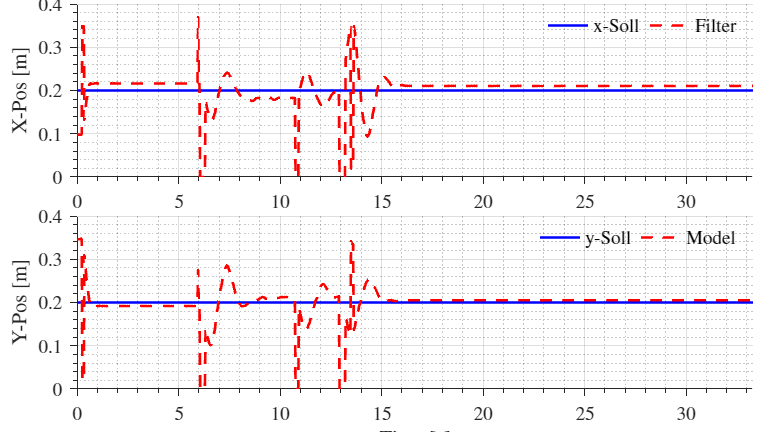

ans = 0.2051


clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
 
% Create axes
axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
hold(axes1,'on');
% Create plot
plot(t,w(:,1),'DisplayName','x-Soll','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
plot(t,y(:,1),'DisplayName','Filter','LineWidth',2,'LineStyle','--','Color',[1 0 0]);

ylim(axes1,[0 0.4]);
xlim([0 max(t)]);

% Create ylabel
ylabel('X-Pos [m]','FontSize',16,'Interpreter','latex');
 
% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='off');
 
% Uncomment the following line to preserve the Y-limits of the axes
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');


hold(axes1,'off');
% Create axes
axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');

hold(axes2,'on');                         

% Create plot
plot(t,w(:,2),'DisplayName','y-Soll','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
plot(t,y(:,2),'DisplayName','Model','LineWidth',2,'LineStyle','--','Color',[1 0 0]);
 
ylim(axes2,[0 0.4]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Y-Pos [m]','FontSize',16,'Interpreter','latex');


% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex');

legend2 = legend(axes2,'show');
set(legend2,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');
 
hold(axes2,'off');

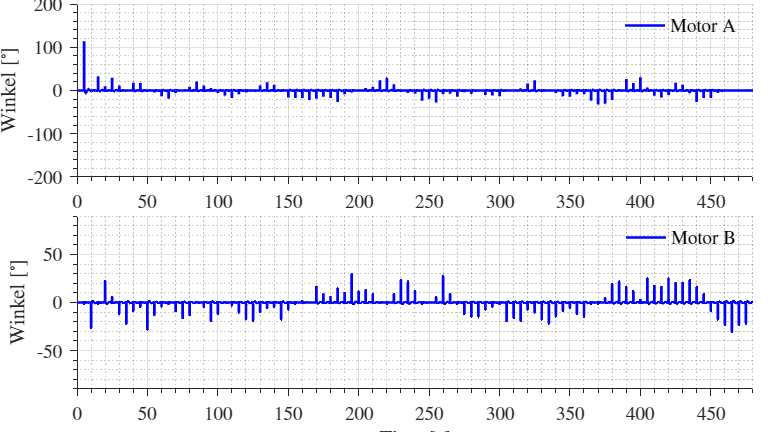


clf
u = rad2deg(out.ymodel.InputData);
t = 0:1/30:(size(u)-1)/30;

clf
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
 
% Create axes
axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
hold(axes1,'on');
% Create plot
stairs(t,u(:,1),'DisplayName','Motor A','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
%plot(t,ykf(:,1),'DisplayName','Filter','LineWidth',2,'LineStyle','--','Color',[1 0 0]);

ylim(axes1,[-200 200]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Winkel [$^\circ$]','FontSize',16,'Interpreter','latex');
 
% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex',Visible='off');
 
% Uncomment the following line to preserve the Y-limits of the axes
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');


hold(axes1,'off');

% axes3 = axes('Parent',figure1,'Position',[0.16 0.55 0.20 0.19],'FontSize',14, ...
%              'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on', ...
%              XTickLabel='');
% hold(axes3,'on');
% % Create plot
% plot(t(1:8:100),u(1:8:100,1),'DisplayName','Motor A','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
% %plot(t,ykf(:,1),'DisplayName','Filter','LineWidth',2,'LineStyle','--','Color',[1 0 0]);
% 
% ylim(axes3,[-200 200]);
% %xlim([0 40]);
% 
% % Create ylabel
% ylabel('Winkel [$^\circ$]','FontSize',16,'Interpreter','latex',Visible='off');
% 
% % Create xlabel
% xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
% 'HorizontalAlignment','center',...
% 'FontSize',16,...
% 'Interpreter','latex',Visible='off');
% 
% % Uncomment the following line to preserve the Y-limits of the axes
% % Create legend
% %legend1 = legend(axes3,'show');
% set(legend1,'Orientation','horizontal','Interpreter','latex',...
% 'FontAngle','italic',...
% 'FontSize',14,...
% 'EdgeColor','none','Color','none','Location','northeast');
% 
% annotation(figure1,'rectangle',...
%     [0.10 0.74 0.03 0.23]);
% 
% hold(axes3,'off');


% Create axes
axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
             'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');

hold(axes2,'on');                         

% Create plot
plot(t,u(:,2),'DisplayName','Motor B','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
%plot(t,ykf(:,2),'DisplayName','Model','LineWidth',2,'LineStyle','--','Color',[1 0 0]);
 
ylim(axes2,[-90 90]);
xlim([0 max(t)]);

% Create ylabel
ylabel('Winkel [$^\circ$]','FontSize',16,'Interpreter','latex');


% Create xlabel
xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
'HorizontalAlignment','center',...
'FontSize',16,...
'Interpreter','latex');

legend2 = legend(axes2,'show');
set(legend2,'Orientation','horizontal','Interpreter','latex',...
'FontAngle','italic',...
'FontSize',14,...
'EdgeColor','none','Color','none','Location','northeast');
 
hold(axes2,'off');